# HW5

clear 
clc 

## prob 1

given a 11-point sequence $x\left(n\right)=10\cdot {\left(\ldotp 6\right)}^n$, for $n\in \left\lbrack 0,10\right\rbrack$, determine and plot ${x\left(\left(n-6\right)\right)}_{16}$.

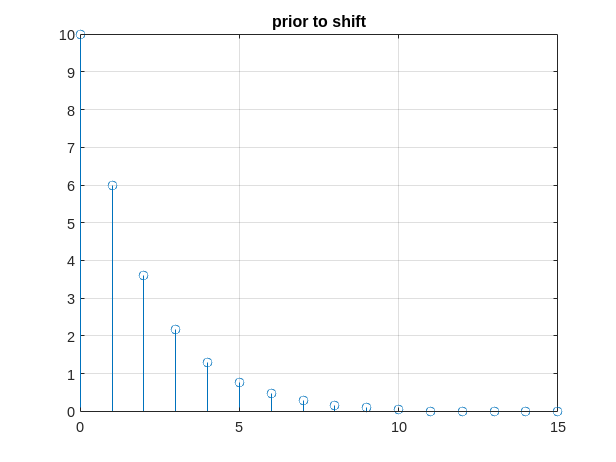

n = 0:10;
x = 10*(.6).^n;
shift = 6;
mod = 16;

append_num = 16 - length(n);

x = [x zeros(1,append_num)];
stem(0:length(x)-1,x)
title('prior to shift')
grid on

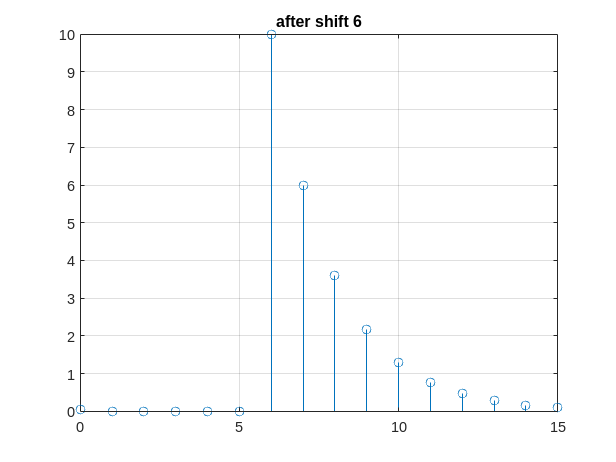


x_shift = circshift(x,shift);
stem(0:length(x)-1,x_shift)
title(sprintf('after shift %d' ,shift))
grid on

## prob 2

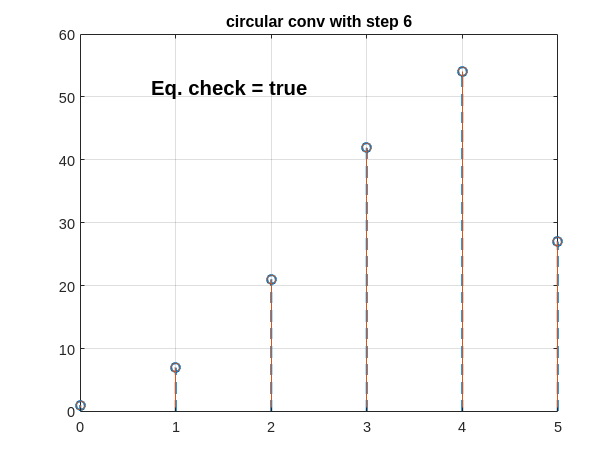

N = 6;
x_1 = [1 4 3];
x_2 = [1 3 6 9];
cconv = circConv2(x_1, x_2, N);

linconv = linConv(x_1,x_2);
figure1 = figure(Name='conv comparison');
stem(0:length(cconv)-1,cconv,LineWidth=1.4,LineStyle="--")
hold on
stem(0:length(linconv)-1,linconv)
title(sprintf('circular conv with step %d' ,N))
grid on
if(length(cconv) == length(linconv))
    res = "true";
else 
    res = "false";
end

annotation(figure1,'textbox',...
    [0.233142857142857 0.752380952380952 0.3215 0.095714285714288],...
    'String',{sprintf('Eq. check = %s',res)},...
    'FontWeight','bold',...
    'FontSize',14,...
    'FitBoxToText','off',...
    'EdgeColor','none');

hold off

The setup only works if N = 6. we cannot have equality unless the number of elements is greater.

## prob 3 - bonus

This is some example code found from the matlab toolbox, I was not sure how to go about it so I got this to learn a better way than my methods.

clear 
clc

x=[1 2 4 8 16 32 32 16 8 4 2 1]

x =      1     2     4     8    16    32    32    16     8     4     2     1


h=[1 3 6 9]

h =      1     3     6     9


L=5

L = 5


% Code to plot X(n)
subplot (2,2,1);
stem(x);
stem(x,'blue');
xlabel ('n---->');
ylabel ('Amplitude ---->');
title('X(n)');

%Code to plot H(n)
subplot (2,2,2);
stem(h);
stem(h,'black');
xlabel ('n---->');
ylabel ('Amplitude ---->');
title(' H(n)');

% Code to perform Convolution using Overlap Save Method
M=length(h);
lx=length(x);
r=rem(lx,L);
x1=[x zeros(1,L-r)];
nr=(length(x1))/L;
h1=[h zeros(1,L-1)];
for k=1:nr
    Ma(k,:)=x1(((k-1)*L+1):k*L)
    if k==1
        Ma1(k,:)=[zeros(1,M-1) Ma(k,:)];
    else 
        Ma1(k,:)=[Ma(k-1,(L-M+2):L) Ma(k,:)];        
    end
     Ma2(k,:)=ifft(mydtft(Ma1(k,:)).*mydtft(h1));
end

Ma =      1     2     4     8    16


Ma =      1     2     4     8    16
    32    32    16     8     4


Ma =      1     2     4     8    16
    32    32    16     8     4
     2     1     0     0     0


Ma3=Ma2(:,M:(L+M-1));
y1=Ma3';
y=y1(:)'

y = 1.0e+02 *

   0.0100 - 0.0000i   0.0500 - 0.0000i   0.1600 - 0.0000i   0.4100 - 0.0000i   0.8200 - 0.0000i   1.6400 - 0.0000i   2.9600 - 0.0000i   4.4800 - 0.0000i   5.3600 + 0.0000i   4.1200 + 0.0000i   2.0600 + 0.0000i   1.0300 - 0.0000i   0.5100 - 0.0000i   0.2400 + 0.0000i   0.0900 - 0.0000i


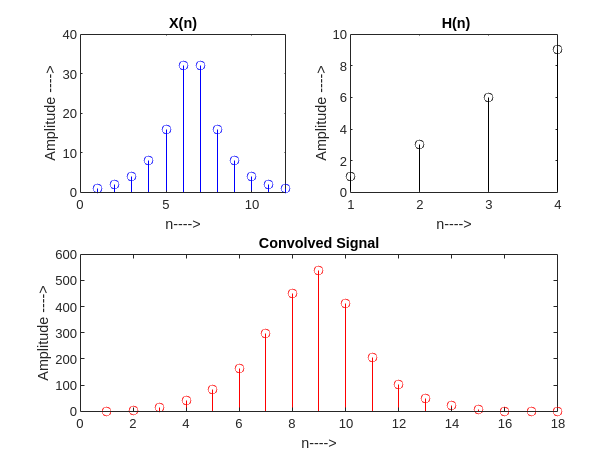



% Representation of the Convolved Signal
subplot (2,2,3:4);

stem(y,'red');

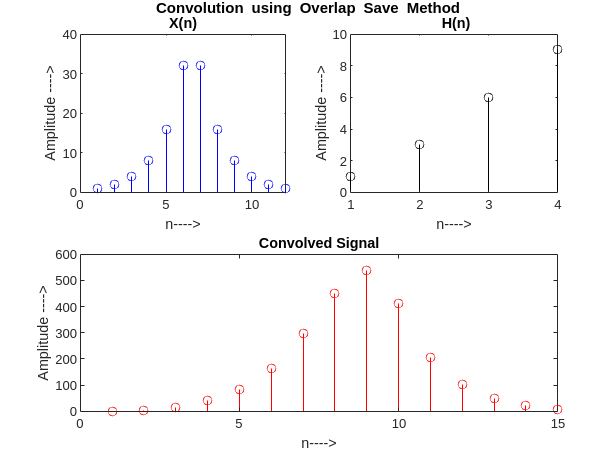

xlabel ('n---->');
ylabel ('Amplitude ---->');
title ('Convolved Signal');
% Add title to the Overall Plot
ha = axes ('Position',[0 0 1 1],'Xlim',[0 1],'Ylim',[0 1],'Box','off','Visible','off','Units','normalized', 'clipping' , 'off');
text (0.5, 1,'\bf Convolution using Overlap Save Method ','HorizontalAlignment','center','VerticalAlignment', 'top')

## prob 4.a

A 12-point sequence is x(n) defined as $x\left(n\right)=\left\lbrace 1\;2\;4\;8\;16\;32\;32\;16\;8\;4\;2\;1\right\rbrace$

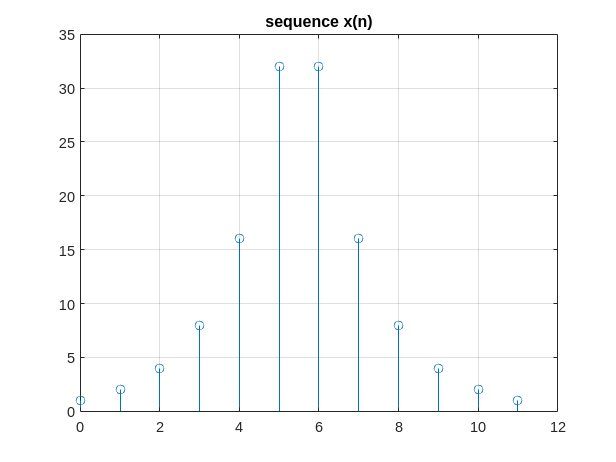

x = [1 2 4 8 16 32 32 16 8 4 2 1];
n = 0:length(x)-1;
figure
stem(n,x)
title('sequence x(n)')
grid on

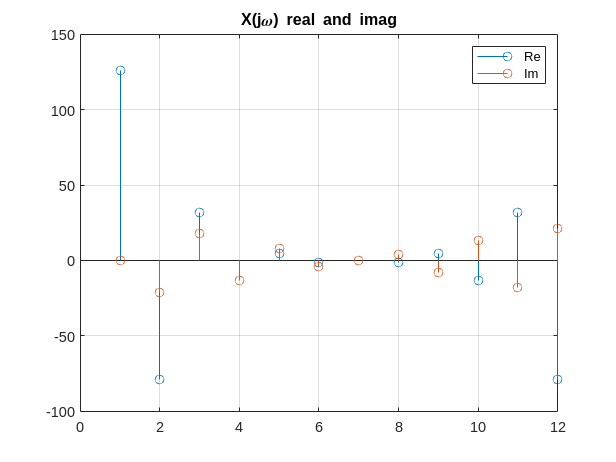

N = 12;
k = n;
figure
X = mydtft(x);

stem(1:length(X),real(X))
hold on
stem(1:length(X),imag(X))
hold off
title('X(j\omega) real and imag')
legend(["Re","Im"])
grid on

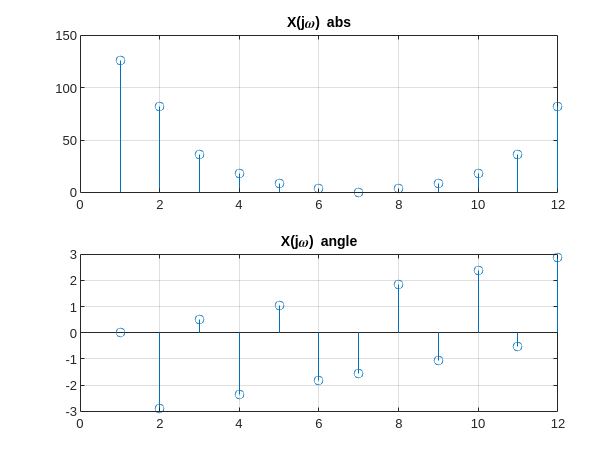

figure
subplot(2,1,1)
stem(abs(X))
title("X(j\omega) abs")
grid on
subplot(2,1,2)
stem(angle(X))
title('X(j\omega) angle')
grid on

## 4.b/c

figure
% Define the anonymous function
X_jw = @(w) sum(x .* exp(-1j * w * n));

% Define the signal x and time indices n
x = [1 2 4 8 16 32 32 16 8 4 2 1];
n = 0:length(x)-1; % Time index

% Define the frequency range from 0 to 2*pi with increments of 0.1
num_points = 512;  % Number of points in frequency axis, for a smooth plot
w = linspace(0, 2*pi, num_points)

w =          0    0.0123    0.0246    0.0369    0.0492    0.0615    0.0738    0.0861    0.0984    0.1107    0.1230    0.1353    0.1476    0.1598    0.1721    0.1844    0.1967    0.2090    0.2213    0.2336    0.2459    0.2582    0.2705    0.2828    0.2951    0.3074    0.3197    0.3320    0.3443    0.3566    0.3689    0.3812    0.3935    0.4058    0.4181    0.4304    0.4427    0.4549    0.4672    0.4795    0.4918    0.5041    0.5164    0.5287    0.5410    0.5533    0.5656    0.5779    0.5902    0.6025


wn = floor(0:num_points/length(n):num_points-1) + 1

wn =      1    43    86   129   171   214   257   299   342   385   427   470


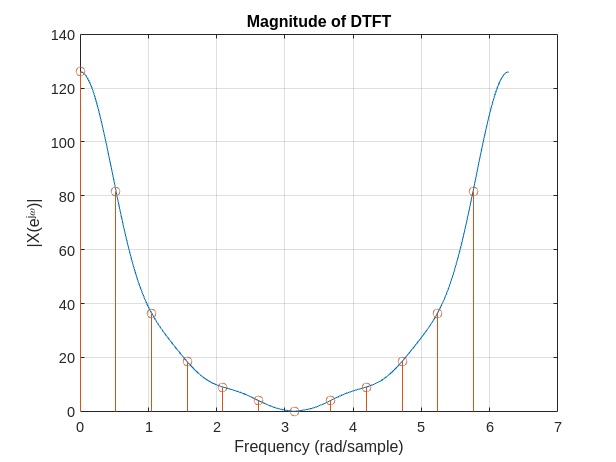

% Calculate the DTFT for each frequency w
X_w = arrayfun(X_jw, w);

% Plot the magnitude of the DTFT
plot(w, abs(X_w));
hold on 
stem(w(wn),abs(X))
grid on
hold off
title('Magnitude of DTFT');
xlabel('Frequency (rad/sample)');
ylabel('|X(e^{j\omega})|');

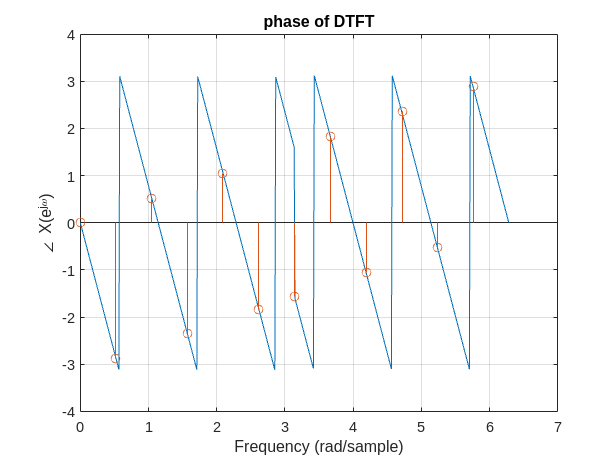

figure
% Plot the magnitude of the DTFT
plot(w, angle(X_w));
hold on 
stem(w(wn),angle(X))
grid on
hold off
title('phase of DTFT');
xlabel('Frequency (rad/sample)');
ylabel('\angle X(e^{j\omega})');

## prob 5 - bonus

x1 = x

x1 =      1     2     4     8    16    32    32    16     8     4     2     1


## just messing around


figure
k = 1;
p = 12;
P = p

P = 12

hold on
xshift = circshift(x,P)

xshift =      1     2     4     8    16    32    32    16     8     4     2     1


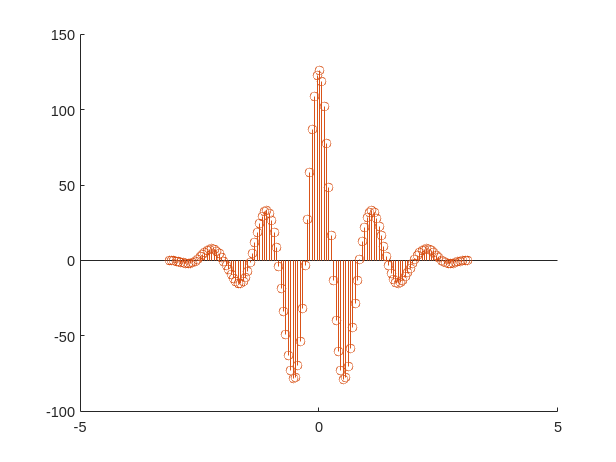

stem(-k*pi:.05:k*pi,real(dtft(xshift,-k*pi:.05:k*pi)))
hold on
stem(-k*pi:.05:k*pi,real(dtft(x,-k*pi:.05:k*pi)))
xlim([-5 5])
%stem(-k*pi:.05:k*pi,imag(mydtft(x,length(-k*pi:.05:k*pi))))
hold off

function [X] = dtft(x, w)
% Computes Discrete-time Fourier Transform
%   X = DTFT values computed at w frequencies
%   x = finite duration sequence over n
%   w = frequency location vector

% Generate the sample position vector n based on the length of x
n = 0:length(x)-1;

% Generate the matrix for the exponential part of the DTFT
% w is a row vector and n is a column vector; use outer product to create the matrix
W = exp(-1i * w(:) * n);

% Compute the DTFT by matrix multiplication
X = W * x(:);

end



function y = circConv(x1, x2, N)
    % Circular Convolution Function using circshift

    % Zero-pad input sequences to length N
    x1 = [x1, zeros(1, N - length(x1))];
    x2 = [x2, zeros(1, N - length(x2))];

    % Pre-allocate the result array for efficiency
    y = zeros(1, N);

    % Perform the circular convolution
    for m = 1:N
        x2_shifted = circshift(x2, [0, m - 1]);
        y(m) = sum(x1 .* x2_shifted);
    end
end


function y = circConv2(x1, x2, N) %Circular Convolution Function

L1 = length(x1);
L2 = length(x2);

%For equation where x_3(m) = sum(from 0 to N-1) (xn)x(m-n)_moduloN equation 2.39 chapt 7
%textbook pg. 484
z1 = [x1 zeros(1, N-L1)];
z2 = [x2 zeros(1, N-L2)];
z = zeros(1,N);
    for m = 1:N
        for n = 1:N
            j = mod(m-n,N);
            j = j + 1;
            z(m) = z(m) + z1(n)*z2(j);
        end
    end

y = z;

end


% toeplitz matrix
function y = circConv3(x1, x2, N)
    % Zero-pad input sequences to length N
    x1 = x1(:).'; % Ensure x1 is a row vector
    x2 = x2(:).'; % Ensure x2 is a row vector
    x1 = [x1 zeros(1, N - length(x1))];
    x2 = [x2 zeros(1, N - length(x2))];

    % Create the circulant matrix of x2
    circulant_x2 = toeplitz([x2(1), x2(end:-1:2)], x2);
    
    % Perform the circular convolution
    y = circulant_x2 * x1.';
end


% toeplitz take 2
function y = circConv4(x1, x2,N)
    % Determine the length N as the length of the longer vector
    N = max(max(length(x1), length(x2)),N);

    % Zero-pad input sequences to length N
    x1 = [x1, zeros(1, N - length(x1))];
    x2 = [x2, zeros(1, N - length(x2))];

    % Create the circulant matrix of x2
    c = [x2(1), fliplr(x2(2:end))]; % The first row for the circulant matrix
    circulant_x2 = toeplitz([x2(1), x2(end:-1:2)], c);
    
    % Perform the circular convolution by matrix multiplication
    y = circulant_x2 * x1.';
end



function y = linConv(x1, x2) 

L1 = length(x1);
L2 = length(x2);

%For equation where x_3(m) = sum(from 0 to N-1) (xn)x(m-n)
z1 = [x1 zeros(1, L2)];
z2 = [x2 zeros(1, L1)];
    for m = 1:L2+L1-1
        z(m)=0;
        for n = 1:L1
            if (m-n+1>0)
                z(m) = z(m) + z1(n)*z2(m-n+1);
                else
            end
        end
    end
y = z;

end

% vec version
function res = mydtft(x)
    N = length(x); % Assuming x is a row vector
    n = 0:N-1; % Time index
    k = n'; % Frequency index (column vector)
    W = exp(-1i * 2 * pi / N * (k * n)); % The DTFT matrix
    res = W * x.';
end
